# HW: Applying Unsupervised Learning to the Cleveland Heart Dataset

## Pre-process the data

- Import the spreadsheet as a table

- Remove rows with missing values

- Normalize each column to have zero mean and unit variance

- Display table properties

% 1. Import spreadsheet as table
heart_data = readtable('cleveland.data_dec2019 - Copy.xlsx');

% 2. Remove rows with missing values
heart_data = rmmissing(heart_data);

% 3. Normalize columns
norm_data = normalize(table2array(heart_data));

## Unsupervised analysis

- Create a clustergram of the entire data (distance = correlation)

- Create a PCA plot based on patients and another based on features

- Find optimal number of patient groups with k-means clustering + silhouette analysis

- Determine whether k-means can be used for diagnosis

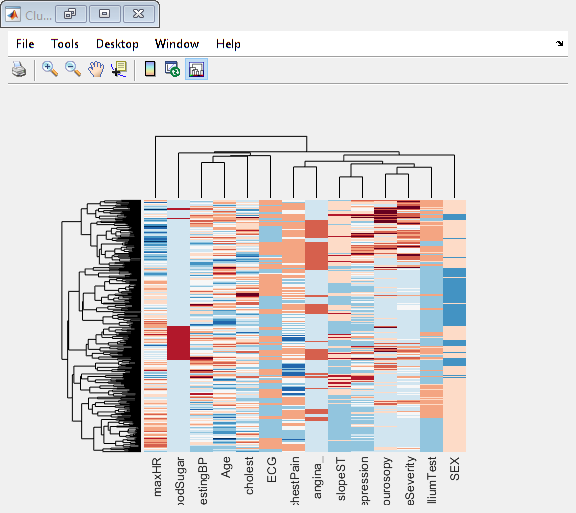

% 1. Create clustergram (distance = correlation)
heart_cg = clustergram(norm_data,...
    'RowLabels',heart_data.diseaseSeverity,...
    'ColumnLabels',heart_data.Properties.VariableNames,...
    'Standardize','column',...
    'RowPDist','correlation','ColumnPDist','correlation',...
    'Colormap',redbluecmap);

% 2a. PCA for patients
mapcaplot(norm_data, heart_data.diseaseSeverity)

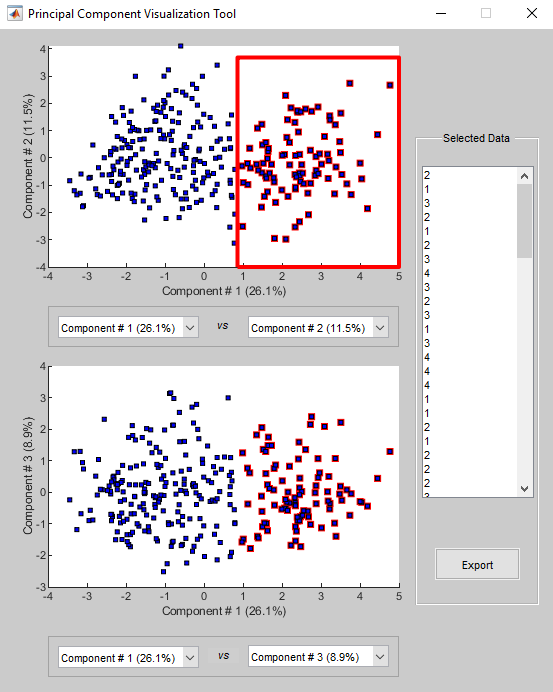

% 2b. PCA for features
mapcaplot(norm_data',heart_data.Properties.VariableNames)

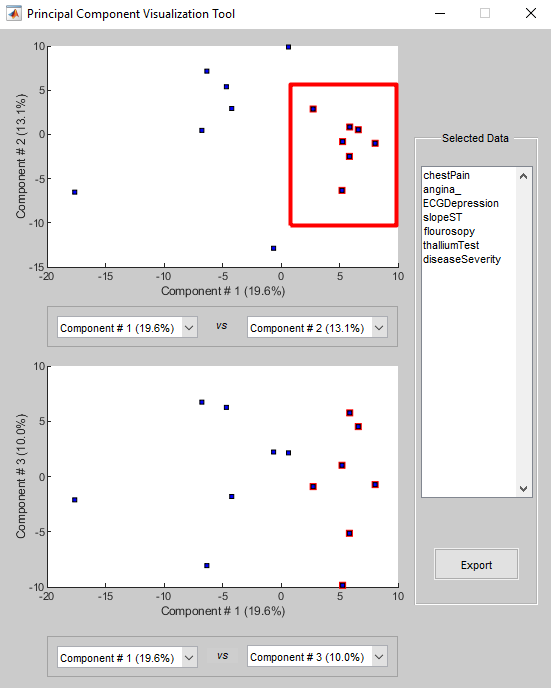

### Q&A

**Question:** Based on clustergram and PCA, how many distinct patient groups are there?

Answer: Clustergram: 4-5, PCA: 2

**Question:** Can the features (columns) be grouped into smaller set of PCs? If so, what are they?

Answer: Yes, these are: chestPain, angina_, ECGDepression, slopeST, flourosopy, thalliumTest, and diseaseSeverity

**Question:** Can patients with heart disease be further classified into smaller groups?

Answer: Yes, see images below:

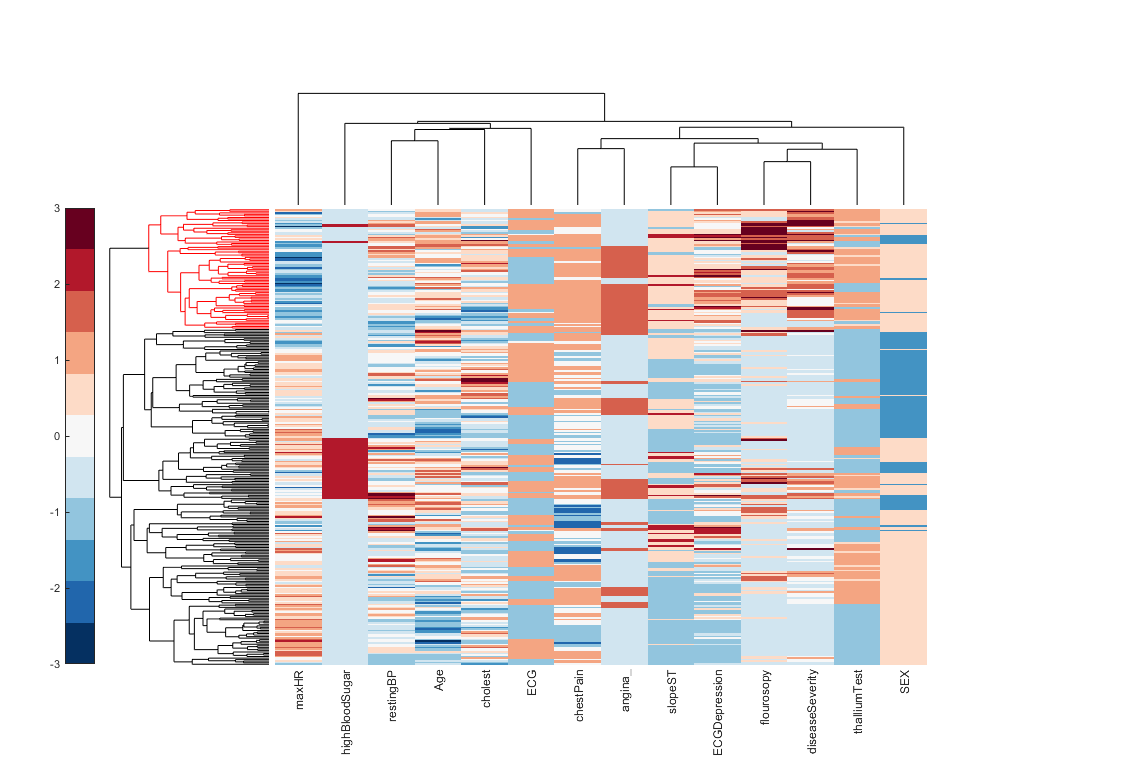

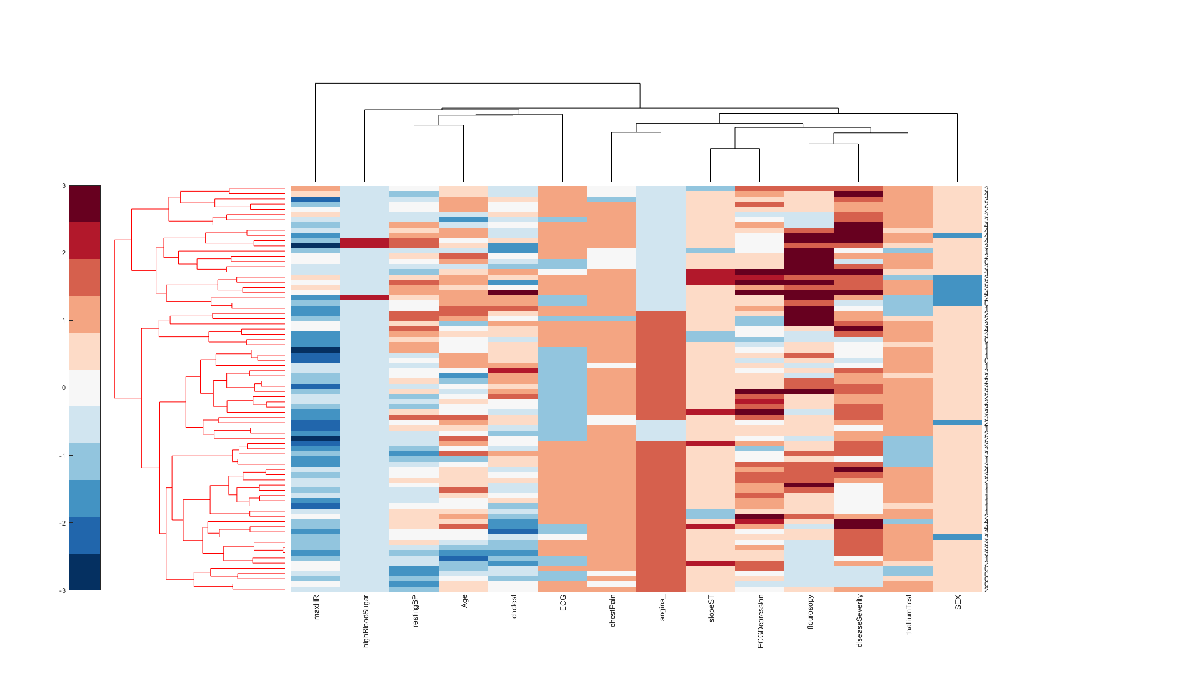

% 3. k-means for determining optimal number of patient groups
k_values = 2:10;
X = table2array(heart_data(:,1:end)); 

% For-loop to calculate the silhouette statistic for different k values
n = length(k_values);   % number of k values
s_score = zeros(n,1);   % variable to store silhouette score values
for i = 1:n
    % Use the kmeans function to cluster patients into k clusters
    idx = kmeans(X,k_values(i));
    % Use the silhouette function to calculate silhouette values
    s = silhouette(X,idx);
    % Calculate the silhouette score by taking the mean
    s_score(i) = mean(s);
end
max(s_score)

ans = 0.5772

k = find(s_score==max(s_score))+1

k = 2

Answer: Optimal k for grouping patients is k = 2.

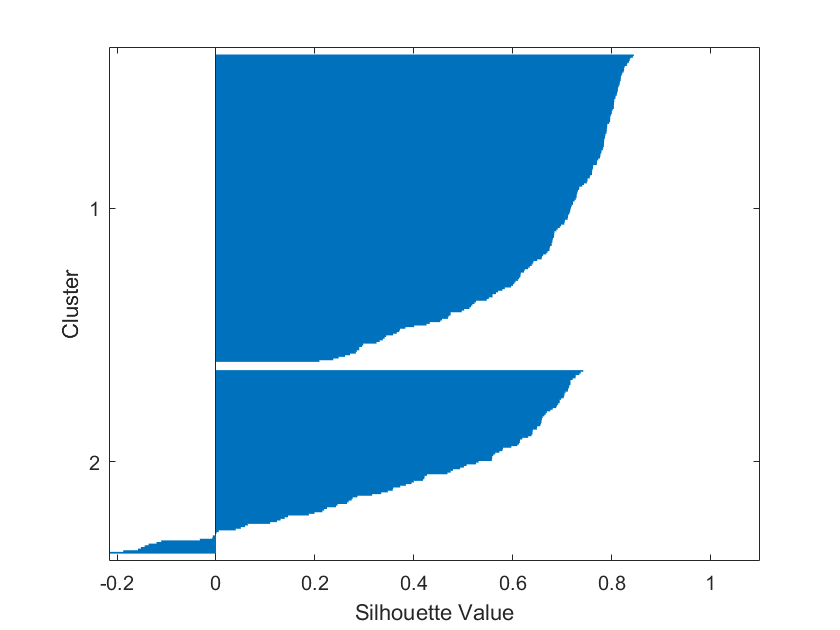

% 4. k-means for diagnosis?
idx = kmeans(X,k);
silhouette(X,idx)

% Vector for normal (0) vs. diseased (1)
heart_disease = zeros(size(heart_data,1),1); 
heart_disease(heart_data.diseaseSeverity > 0) = 1; 

% Cluster 1 (40.86% diseased)
c1 = heart_disease(idx == 1); sum(c1)/length(c1)

ans = 0.4086

% Cluster 2 (54.95% diseased)
c2 = heart_disease(idx == 2); sum(c2)/length(c2)

ans = 0.5495

Answer: K-means is not a great tool to use for diagnosis (does not clearly separate normal and diseased patients).